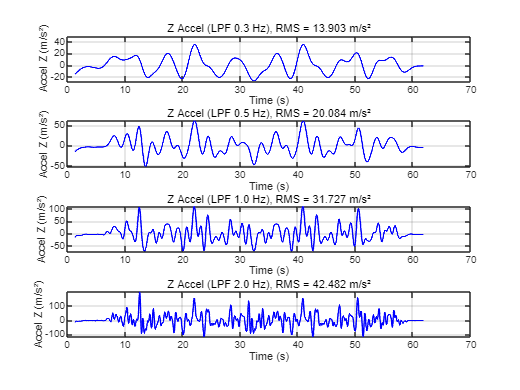

% === Load IMU Data ===
data = readtable('imu1.csv');         % 파일명 필요 시 변경
t = data.Time_ms / 1000;              % Time in seconds
raw_Az = data.AccelZ_g;               % Z-axis acceleration (could be in g or m/s²)

% === Sampling Frequency ===
fs = 1 / mean(diff(t));               % Hz

% === Auto Scale Detection and Gravity Removal ===
if mean(raw_Az) > 20  % Already in m/s²
    Az = raw_Az - mean(raw_Az);       % Remove gravity
else                  % Likely in g
    Az = raw_Az * 9.80665;
    Az = Az - mean(Az);
end

% === LPF Cutoff Frequencies to Test ===
cutoff_list = [0.3, 0.5, 1.0, 2.0];
rms_results = zeros(size(cutoff_list));

% === Filtering + Plotting + RMS ===
figure;
for i = 1:length(cutoff_list)
    fc = cutoff_list(i);
    
    % LPF Design
    [b, a] = butter(4, fc / (fs/2), 'low');
    Az_filt = filtfilt(b, a, Az);

    % RMS 계산
    rms_results(i) = rms(Az_filt);

    % Plot
    subplot(length(cutoff_list), 1, i);
    plot(t, Az_filt, 'b', 'LineWidth', 1.2);  % → 색상 변경: 파란색
    title(sprintf('Z Accel (LPF %.1f Hz), RMS = %.3f m/s²', fc, rms_results(i)));
    xlabel('Time (s)');
    ylabel('Accel Z (m/s²)');
    grid on;
end


% === Summary Table 출력 ===
T_rms = table(cutoff_list', rms_results', ...
    'VariableNames', {'Cutoff_Hz', 'Z_Accel_RMS_mps2'});
disp(T_rms);

    Cutoff_Hz    Z_Accel_RMS_mps2
    _________    ________________

       0.3            13.903     
       0.5            20.084     
         1            31.727     
         2            42.482     

